
% Get all .wav files in the directory
files = dir(fullfile('Training_Data', '*.wav'));

% Extract numeric values from filenames for correct sorting
fileNames = {files.name};
numValues = zeros(length(fileNames), 1);

for i = 1:length(fileNames)
    numStr = regexp(fileNames{i}, '\d+', 'match'); % Extract numeric part
    numValues(i) = str2double(numStr{1}); % Convert to number
end

% Sort files numerically
[~, sortedIdx] = sort(numValues);
files = files(sortedIdx); % Reorder file structure

% Number of files
numFiles = length(files);

% Define subplot grid size (adjust dynamically)
rows = ceil(sqrt(numFiles));  % Auto-adjust rows
cols = ceil(numFiles / rows); % Auto-adjust columns
numPlots = min(numFiles, rows * cols); % Ensure we don't exceed available subplots

figure; % Create a new figure


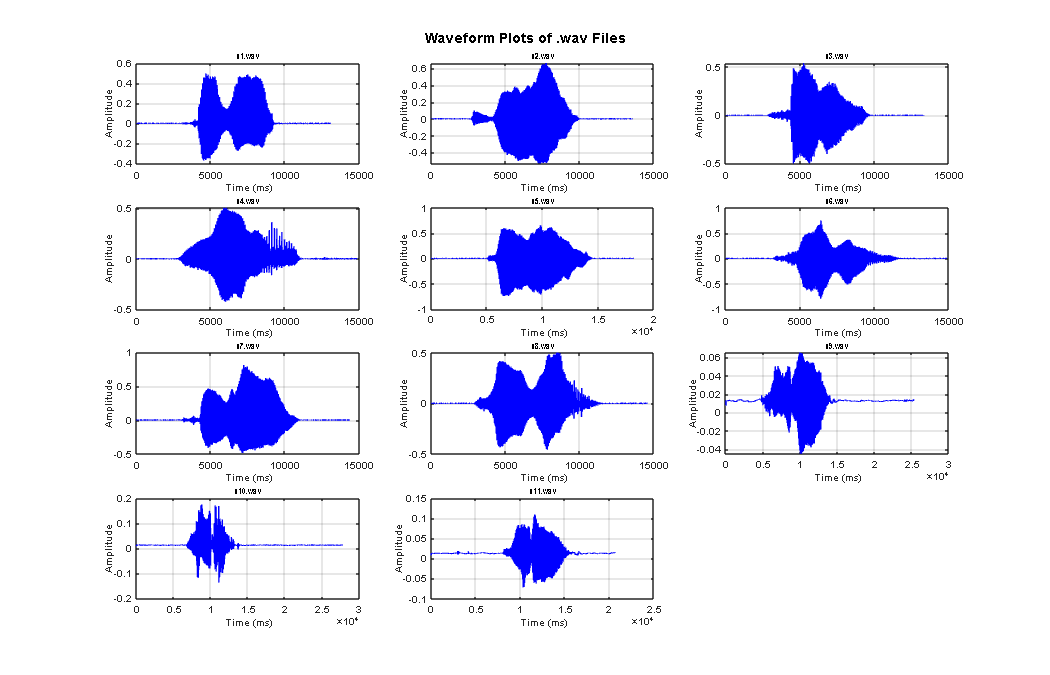



for i = 1:numPlots
    % Construct full filename
    filename = fullfile(files(i).folder, files(i).name);
    
    % Read the audio file
    [signal, fs] = audioread(filename);

    %normalize signal
    %signal = normalize(signal, 'range', [-1,1]); 
    
    % Convert stereo to mono (if necessary)
    if size(signal, 2) == 2
        signal = mean(signal, 2); % Take the average of both channels
    end
    
    % Select subplot position
    subplot(rows, cols, i);
    plot(signal, 'b'); % Force a consistent color (blue)
    
    % Formatting each subplot
    title(files(i).name, 'Interpreter', 'none', 'FontSize', 8);
    xlabel('Time (ms)');
    ylabel('Amplitude');
    grid on;
end

% Adjust figure layout
sgtitle('Waveform Plots of .wav Files', 'FontSize', 14, 'FontWeight', 'bold'); % Overall title
set(gcf, 'Position', [100, 100, 1400, 900]); % Resize figure for better layout

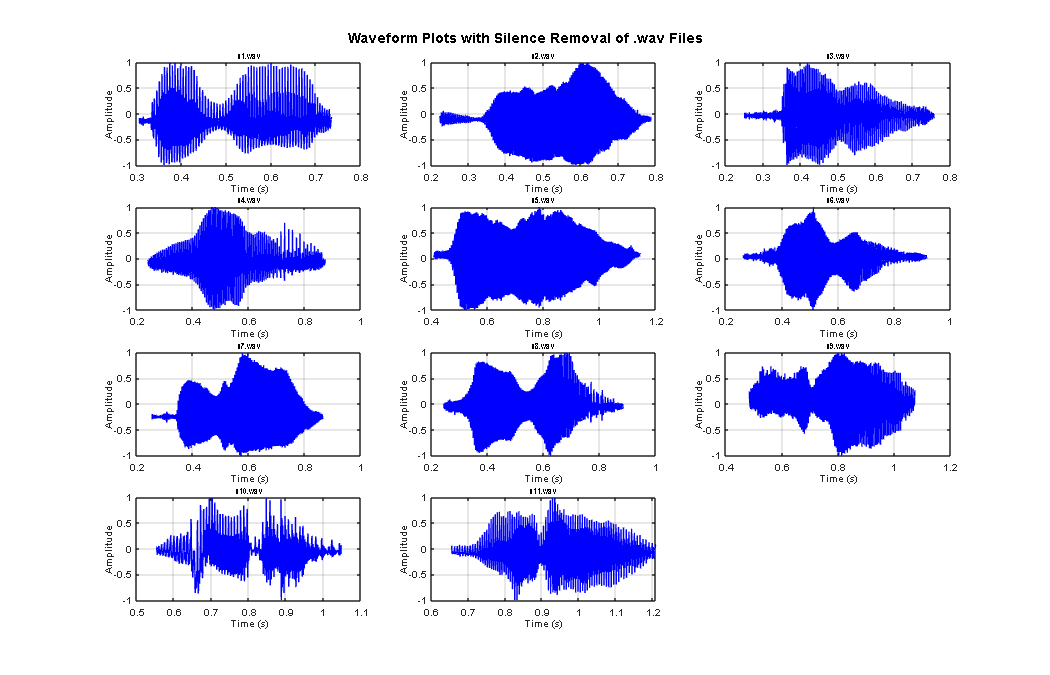

%voice audio detection. removal of signal that is in silence or below 35(?)
energyThreshold = 0.0005; % Adjust this threshold for silence detection


for i = 1:numPlots
    % Construct full filename
    filename = fullfile(files(i).folder, files(i).name);
    
    % Read the audio file
    [signal, fs] = audioread(filename);

    % Normalize the signal
    %signal = normalize(signal, 'range', [-1, 1]);
    
    % Convert stereo to mono (if necessary)
    if size(signal, 2) == 2
        signal = mean(signal, 2); % Take the average of both channels
    end
    
    % Remove silence at the beginning and end using energy threshold
    % Calculate the energy of the signal (squared values)
    energy = signal.^2;
    
    % Define a threshold to consider the signal as non-silent
    nonSilentIdx = energy > energyThreshold;
    
    % Find the indices of the non-silent portion
    speechStart = find(nonSilentIdx, 1, 'first');
    speechEnd = find(nonSilentIdx, 1, 'last');
    
    % Trim the signal to include only the non-silent portion
    trimmedSignal = signal(speechStart:speechEnd);

    %normalize trimmed signal
    signal = normalize(trimmedSignal, 'range', [-1,1]); 

    % Select subplot position
    subplot(rows, cols, i);
    plot((speechStart:speechEnd)/fs, signal, 'b'); % Plot the trimmed signal
    
    % Formatting each subplot
    title(files(i).name, 'Interpreter', 'none', 'FontSize', 8);
    xlabel('Time (s)');
    ylabel('Amplitude');
    grid on;
end

% Adjust figure layout
sgtitle('Waveform Plots with Silence Removal of .wav Files', 'FontSize', 14, 'FontWeight', 'bold'); % Overall title

set(gcf, 'Position', [100, 100, 1400, 900]);


window = 256

window = 256

overlap = window - (window/3);
nfft = 256

nfft = 256

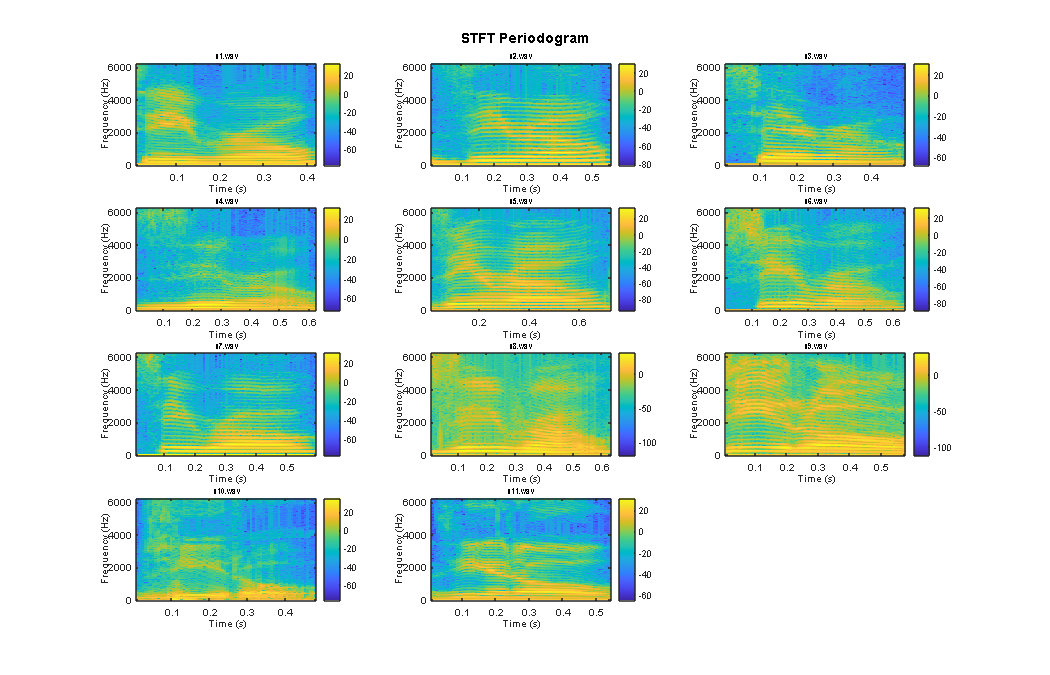



% Define subplot grid size (adjust dynamically)
rows = ceil(sqrt(numFiles));  % Auto-adjust rows
cols = ceil(numFiles / rows); % Auto-adjust columns
numPlots = min(numFiles, rows * cols); % Ensure we don't exceed available subplots

figure; % Create a new figure


for i = 1:numPlots
    % Construct full filename
    filename = fullfile(files(i).folder, files(i).name);
    
    % Read the audio file
    [signal, fs] = audioread(filename);

    % Normalize the signal
    %signal = normalize(signal, 'range', [-1, 1]);
    
    % Convert stereo to mono (if necessary)
    if size(signal, 2) == 2
        signal = mean(signal, 2); % Take the average of both channels
    end
    
    % Remove silence at the beginning and end using energy threshold
    % Calculate the energy of the signal (squared values)
    energy = signal.^2;
    
    % Define a threshold to consider the signal as non-silent
    nonSilentIdx = energy > energyThreshold;
    
    % Find the indices of the non-silent portion
    speechStart = find(nonSilentIdx, 1, 'first');
    speechEnd = find(nonSilentIdx, 1, 'last');
    
    % Trim the signal to include only the non-silent portion
    trimmedSignal = signal(speechStart:speechEnd);

    %normalize trimmed signal
    signal = normalize(trimmedSignal, 'range', [-1,1]); 

    %do stft 
    [s,f,t] = stft(signal, fs, 'Window', hamming(window), 'OverlapLength', round(overlap), 'FFTLength', nfft);
    
    % Select only positive frequencies
    positiveFreqIdx = f >= 0; 
    

    subplot(rows, cols, i);
    %imagesc(t, f(positiveFreqIdx), real(s(positiveFreqIdx, :)));
    imagesc(t, f(positiveFreqIdx), 20*log10(abs(s(positiveFreqIdx, :)) + eps));
    %eps revents a log(0)

    axis xy;
    xlabel('Time (s)');
    ylabel('Frequency (Hz)');
    title(files(i).name, 'Interpreter', 'none', 'FontSize', 8);

    colorbar;


end

% Adjust figure layout
sgtitle('STFT Periodogram' , 'FontSize', 14, 'FontWeight', 'bold'); % Overall title
set(gcf, 'Position', [100, 100, 1400, 900]); % Resize figure for better layout

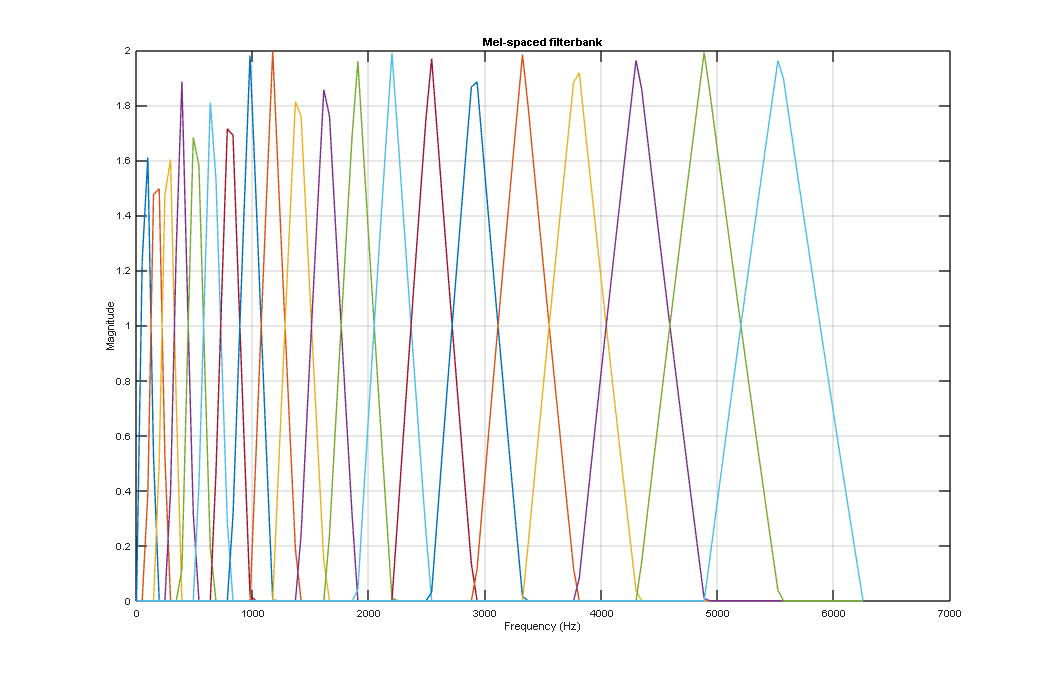

fs = 12500;       % Sampling frequency (Hz)
nfft = 256;       % FFT size
k = 20;  % Number of Mel filters

% Generate Mel filter bank (requires Voicebox Toolbox)
%melfilterbank = melbankm(k, nfft, fs, 0, 0.5, 'm'); 
melfilterbank = melfb(k,nfft,fs);
%disp(melfb);
% Frequency axiss in Hz
freqs = linspace(0, fs/2, nfft/2+1); 

% Plot Mel filter bank response
figure;
plot(freqs, melfilterbank');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Mel-spaced filterbank');
grid on;


set(gcf, 'Position', [100, 100, 1400, 900]); % Resize figure for better layout

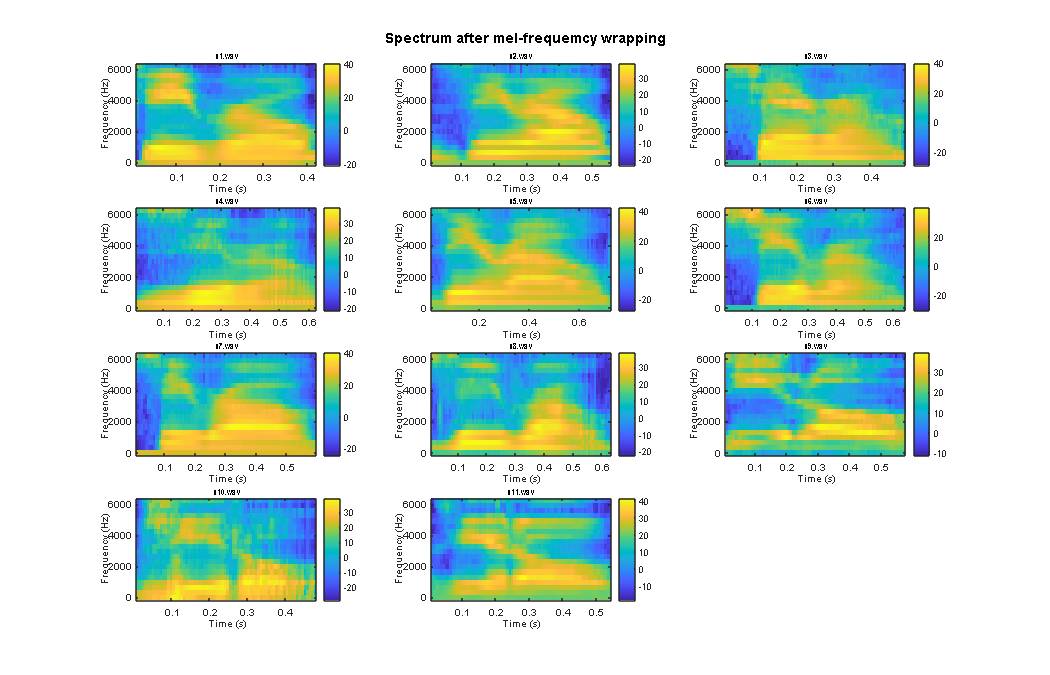

% Parameters
window = 256;
overlap = window - (window/3);
nfft = 256;

% Define subplot grid size (adjust dynamically)
rows = ceil(sqrt(numFiles));  % Auto-adjust rows
cols = ceil(numFiles / rows); % Auto-adjust columns
numPlots = min(numFiles, rows * cols); % Ensure we don't exceed available subplots

figure; % Create a new figure

for i = 1:numPlots
    % Construct full filename
    filename = fullfile(files(i).folder, files(i).name);
    
    % Read the audio file
    [signal, fs] = audioread(filename);

    % Normalize the signal
    %signal = normalize(signal, 'range', [-1, 1]);
    
    % Convert stereo to mono (if necessary)
    if size(signal, 2) == 2
        signal = mean(signal, 2); % Take the average of both channels
    end
    
    % Remove silence at the beginning and end using energy threshold
    % Calculate the energy of the signal (squared values)
    energy = signal.^2;
    
    % Define a threshold to consider the signal as non-silent
    nonSilentIdx = energy > energyThreshold;
    
    % Find the indices of the non-silent portion
    speechStart = find(nonSilentIdx, 1, 'first');
    speechEnd = find(nonSilentIdx, 1, 'last');
    
    % Trim the signal to include only the non-silent portion
    trimmedSignal = signal(speechStart:speechEnd);

    %normalize trimmed signal
    signal = normalize(trimmedSignal, 'range', [-1,1]); 

    % Perform STFT
    [s, f, t] = stft(signal, fs, 'Window', hamming(window), 'OverlapLength', round(overlap), 'FFTLength', nfft);
    
     % Select only positive frequencies
    positiveFreqIdx = f >= 0; 
    f_pos = f(positiveFreqIdx);
    s_pos = s(positiveFreqIdx, :);

    %imagesc(t, f(positiveFreqIdx), real(s(positiveFreqIdx, :)));
    %imagesc(t, f(positiveFreqIdx), 20*log10(abs(s(positiveFreqIdx, :)) + eps));
    %eps revents a log(0)


    % Apply mel filter bank if necessary
    melfb_response = melfilterbank * abs(s_pos);
    
    
    % Create the subplot
    subplot(rows, cols, i);
    
    % Plot only positive frequencies
    imagesc(t, f_pos, 20*log10(abs(melfb_response) + eps)); % eps avoids log(0)
    
    % Adjust plot axes and labels
    axis xy;
    xlabel('Time (s)');
    ylabel('Frequency (Hz)');
    title(files(i).name, 'Interpreter', 'none', 'FontSize', 8);

    colorbar;
end

% Adjust figure layout
sgtitle('Spectrum after mel-frequemcy wrapping', 'FontSize', 14, 'FontWeight', 'bold'); % Overall title
set(gcf, 'Position', [100, 100, 1400, 900]); % Resize figure for better layout

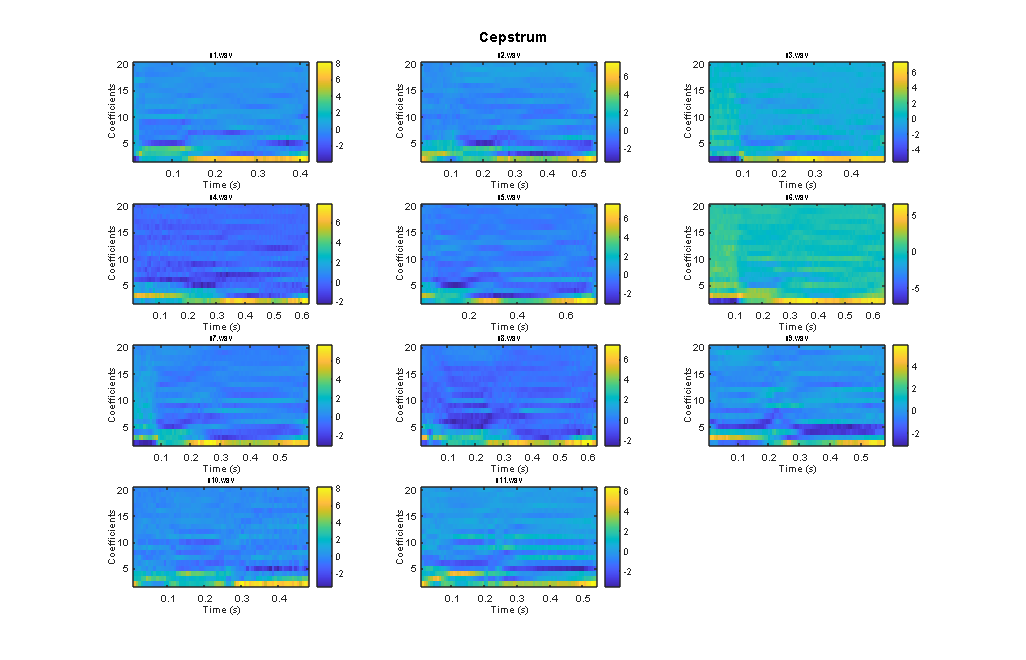

% Parameters
window = 256;
overlap = window - (window/3);
nfft = 256;

% Define subplot grid size (adjust dynamically)
rows = ceil(sqrt(numFiles));  % Auto-adjust rows
cols = ceil(numFiles / rows); % Auto-adjust columns
numPlots = min(numFiles, rows * cols); % Ensure we don't exceed available subplots

figure; % Create a new figure

for i = 1:numPlots
    % Construct full filename
    filename = fullfile(files(i).folder, files(i).name);
    
    % Read the audio file
    [signal, fs] = audioread(filename);

    % Normalize the signal
    %signal = normalize(signal, 'range', [-1, 1]);
    
    % Convert stereo to mono (if necessary)
    if size(signal, 2) == 2
        signal = mean(signal, 2); % Take the average of both channels
    end
    
for i = 1:numPlots
    % Construct full filename
    filename = fullfile(files(i).folder, files(i).name);
    
    % Read the audio file
    [signal, fs] = audioread(filename);

    % Normalize the signal
    %signal = normalize(signal, 'range', [-1, 1]);
    
    % Convert stereo to mono (if necessary)
    if size(signal, 2) == 2
        signal = mean(signal, 2); % Take the average of both channels
    end
for i = 1:numPlots
    % Construct full filename
    filename = fullfile(files(i).folder, files(i).name);
    
    % Read the audio file
    [signal, fs] = audioread(filename);

    % Normalize the signal
    %signal = normalize(signal, 'range', [-1, 1]);
    
    % Convert stereo to mono (if necessary)
    if size(signal, 2) == 2
        signal = mean(signal, 2); % Take the average of both channels
    end
    
    % Remove silence at the beginning and end using energy threshold
    % Calculate the energy of the signal (squared values)
    energy = signal.^2;
    
    % Define a threshold to consider the signal as non-silent
    nonSilentIdx = energy > energyThreshold;
    
    % Find the indices of the non-silent portion
    speechStart = find(nonSilentIdx, 1, 'first');
    speechEnd = find(nonSilentIdx, 1, 'last');
    
    % Trim the signal to include only the non-silent portion
    trimmedSignal = signal(speechStart:speechEnd);

    %normalize trimmed signal
    %normalizing changes the size of the window ....
    signal = normalize(trimmedSignal, 'range', [-1,1]); 
    
    % Perform STFT
    [s, f, t] = stft(signal, fs, 'Window', hamming(window), 'OverlapLength', round(overlap), 'FFTLength', nfft);
    
     % Select only positive frequencies
    positiveFreqIdx = f >= 0; 
    f_pos = f(positiveFreqIdx);
    s_pos = s(positiveFreqIdx, :);

    % Apply mel filter bank
    melfb_response = melfilterbank * abs(s_pos);
    logMelSpectrogram = log(melfb_response);
    cepstrum = dct(logMelSpectrogram);
    numCoefficients = 20;  
    cepstrum = cepstrum(2:numCoefficients, :);
    %disp(filename);
    %disp(cepstrum);

    % Create the subplot
    subplot(rows, cols, i);
    
    % Plot only positive frequencies
    %imagesc(t, cepstrum(1,:), 20*log(abs(cepstrum))); % eps avoids log(0)
    imagesc(t, 2:numCoefficients, cepstrum)
    % Adjust plot axes and labels
    axis xy;
    xlabel('Time (s)');
    ylabel('Coefficients');
    title(files(i).name, 'Interpreter', 'none', 'FontSize', 8);
    
    colorbar;
end

% Adjust figure layout
sgtitle('Cepstrum', 'FontSize', 14, 'FontWeight', 'bold'); % Overall title
set(gcf, 'Position', [100, 100, 1400, 900]); % Resize figure for better layout

%disp(cepstrum)

